clc; clear; clf;

 
cellName = "Cell 1";
batteryType = "VTC6";

topFileLocation = 'MIT Motorsports Cell Data 2019\';
topDir = dir(topFileLocation);                      %directory
topNames = {topDir(:).name}';                       %get the names of all files from the directory

allCells = topNames(startsWith(topNames,cellName)); %search for ones that start with cellName
cellNum = fullfile(allCells);                       %full file location of search results

for j = 1:length(cellNum)
    
    cellDir = dir(strcat(topFileLocation,char(cellNum(j))));
    fileNames = {cellDir(:).name}';
    cellNames = fileNames(startsWith(fileNames, batteryType));
    t40Files = cellNames(contains(cellNames,"_40_"));
    t60Files = cellNames(contains(cellNames,"_60_"));
    t40CSV = fullfile(strcat(topFileLocation,char(cellNum(j))),t40Files);
    t60CSV = fullfile(strcat(topFileLocation,char(cellNum(j))),t60Files);
    
    fitIR = [];
    fitSOC = [];
    fitV = [];
    fitVSOC = [];
            
        for i = 1:length(t40CSV)
            
            temp40 = importfile(char(t40CSV(i)));                                            %this means temporary not temperature
            [Bat(j,i).Raw.Temp40.IR, Bat(j,i).Raw.Temp40.SOC] ...
                = peakFilter1(temp40.Amps,temp40.Volts,temp40.Times);                          
            fitIR = vertcat(fitIR, Bat(j,i).Raw.Temp40.IR);
            fitSOC = vertcat(fitSOC, Bat(j,i).Raw.Temp40.SOC);
        end
    [IRcurve(j).Temp40.fit, IRcurve(j).Temp40.gof] = VTC6FIT(fitSOC, fitIR);
    fitIR = [];
    fitSOC = [];
    
        for k = 1:length(t60CSV)
            temp60 = importfile(char(t60CSV(k)));                                            %this means temporary not temperature
            [Bat(j,k).Raw.Temp60.IR, Bat(j,k).Raw.Temp60.SOC] ...
                = peakFilter1(temp60.Amps,temp60.Volts,temp60.Times);
            fitIR60 = vertcat(fitIR, Bat(j,k).Raw.Temp60.IR);
            fitSOC60 = vertcat(fitSOC, Bat(j,k).Raw.Temp60.SOC); 
%             fitVolt = vertcat(fitVolt, Bat(j,i).Raw.Temp60.Volt);
        end 
    [IRcurve(j).Temp60.fit, IRcurve(j).Temp60.gof] = VTC6FIT(fitSOC60, fitIR60);
    fitIR = [];
    fitSOC = [];
end

%Bat :
%   Cell 1
%   Cell 10
%   Cell 100
%   Cell 2
%   Cell 3
%    .
%    .
%    .
%   Cell 9


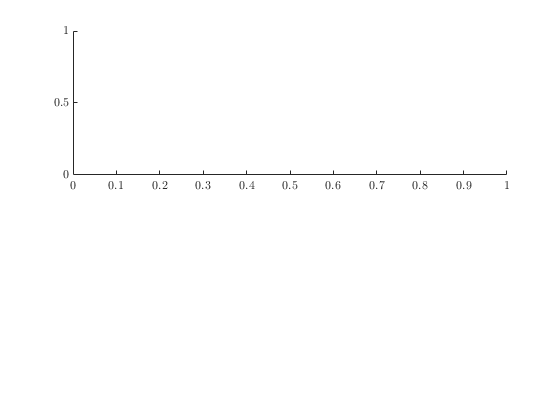

subplot(2,1,1)

plot(0:0.1:2.5 ,temp40.Amps(3970:3995)), ylabel("Current (A)");

Unable to resolve the name temp40.Amps.

subplot(2,1,2)
plot(0:0.1:2.5 ,temp40.Volts(3970:3995)), ylabel ("Voltage (V)"), xlabel("Times (s)");
chg = [10 50 90];
Results.raw.temp40=[];
Results.raw.temp60=[];

for i = 1:length(cellNum) 
  Results.raw.temp40 =  horzcat(Results.raw.temp40, IRcurve(i).Temp40.fit(chg));
  Results.raw.temp60 =  horzcat(Results.raw.temp60, IRcurve(i).Temp60.fit(chg));
end

%Results :
       % 10% SOC
       % 50% SOC
       % 90% SOC
       
Results.temp40.mean = mean(Results.raw.temp40,2);
Results.temp40.dev = std(Results.raw.temp40,0,2);
       
Results.temp60.mean = mean(Results.raw.temp60,2);
Results.temp60.dev = std(Results.raw.temp60,0,2);


%%=======================================================================================
%% Object Creation
addpath( 'C:\Users\cdrow\Desktop\UCDavis\Spring 2020\Senior Design' );
VTC6_IR = InternalResistance( 'FE8', Results, batteryType);

cd( 'C:\Users\cdrow\Desktop\UCDavis\Spring 2020\Senior Design\MIT Cell Analysis' )
save( [VTC6_IR.Name, '.mat'], 'VTC6_IR' );

%%======================================================================================


function [Data] = importfile(filename, dataLines)
    if nargin < 2
        dataLines = [7, Inf];
    end

    opts = delimitedTextImportOptions("NumVariables", 6);

    % Specify range and delimiter
    opts.DataLines = dataLines;
    opts.Delimiter = ",";

    % Specify column names and types
    opts.VariableNames = ["Times", "Volts", "Amps", "Var4", "Var5", "Var6"];
    opts.SelectedVariableNames = ["Times", "Volts", "Amps"];
    opts.VariableTypes = ["double", "double", "double", "string", "string", "string"];

    % Specify file level properties
    opts.ExtraColumnsRule = "ignore";
    opts.EmptyLineRule = "read";

    % Specify variable properties
    opts = setvaropts(opts, ["Var4", "Var5", "Var6"], "WhitespaceRule", "preserve");
    opts = setvaropts(opts, ["Var4", "Var5", "Var6"], "EmptyFieldRule", "auto");

    % Import the data
    Q14023 = readtable(filename, opts);
    
    % Convert to output type
    Data.Times = Q14023.Times;
    Data.Volts = Q14023.Volts;
    Data.Amps = Q14023.Amps;
end

function [IR,SOC] = peakFilter1(i, v, time)
    di = diff(i);
    di(1:500) = [];
    v(1:500) = [];

    %finding the average with the zeros removed
    temp1 = di(di~=0);
    avgI = mean(temp1);
    
    di(length(di)-400:length(di)) = [];
    v(length(v)-1) =[];
    v(length(v)-400:length(v)) = [];
    
    soc = 100 - cumsum([0; diff(time)].*i./10800.*100);
    soc(1:501) = [];
    soc(length(soc)-400:length(soc)) = [];
    
    Vselect = zeros(length(v), 1);
    dI = zeros(length(v), 1);
    dV = zeros(length(v),1);
    filter = zeros(length(v), 1);
    filterNot = ones(length(v), 1);
    
    di(1:4) = 0;
    % this loop finds current interupts above a threshold (100 x avg)
    % then creates a voltage array with the values surrounding the peaks
    for i = 4:length(di)
        if (di(i) <= (50*avgI))
            di(i) = 0;
        elseif (di(i) > (50*avgI)) && (3 < i < length(di)-4)
            for j = -3:3
                Vselect(i + j) = v(i+j);
            end
        end
    end
    
    %this computes the total initial current change
    %and the voltage change around it
    %once it finds a peak it skips ahead to ignore subsequent changes
    
%      IR = [Vselect, di];
%      IR( ~any(IR,2), : ) = [];
    
    k = 4;
    while k  < length(di)
        sumdI = 0;
        if (di(k) ~= 0)
            filter(k) = 1;
%             for h = -6:6
%                 filterNot(k+h) = 0;
%             end
            for j = -3:3 
                nextdI = di(k + j);
                sumdI = sumdI + nextdI;
            end 
            dV(k) = Vselect(k -3) - Vselect(k + 3);
            dI(k) = sumdI;
            k = k + 3;
        end
        k = k + 1;
    end
    
%     fsoc = soc.*filterNot;
%     VOLT = v.*filterNot;
%     fsoc = fsoc(fsoc~=0);
%     VOLT = VOLT(VOLT~=0);
    
    soc = soc.*filter;
    SOC = soc(soc~=0);
    dV = dV(dV~=0);
    dI = dI(dI~=0);
    IR = dV./dI;
%     IR = [dV, dI];
%     IR( ~any(IR,2), : ) = [];
%     IR(length(IR)+1:minL) = 0;
end


function [fitresult, gof] = VTC6FIT(x, y)
%CREATEFIT(X,Y)
%  Create a fit.
%
%  Data for 'VTC6 Cell2' fit:
%      X Input : x
%      Y Output: y
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 29-May-2020 11:41:46


%% Fit: 'VTC6 Cell2'.
[xData, yData] = prepareCurveData( x, y );

% Set up fittype and options.
ft = fittype( 'smoothingspline' );
opts = fitoptions( 'Method', 'SmoothingSpline' );
opts.SmoothingParam = 20e-4;
% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
% figure( 'Name', 'VTC6 Cell2' );
% h = plot( fitresult, xData, yData );
% legend( h, 'y vs. x', 'VTC6 Cell2', 'Location', 'NorthEast', 'Interpreter', 'none' );
% % Label axes
% xlabel( 'x', 'Interpreter', 'none' );
% ylabel( 'y', 'Interpreter', 'none' );
% grid on
end